# For all the218, 4 node network topologies possible, for boolean simulation results, phase frequency distribution JSD is caculated with that of TTr as reference

## Reading the 218 networks' boolean results

% In the 'Topofiles_results' folder boolean simulation results for all 
% the 218 four node networks are present. In the file names 'n_m' 
% form, 'n' represents the number of edges that have been swapped
% to activation and 'm' represents the mth variant of the 'n' 
% edge swapped networks.

clear all

% path to the Topofiles_results folder
% folder_path_parent = '/Topofiles_results/';
folder_path = ['/Users/atchutasrinivasduddu/Library/CloudStorage/' ...
    'OneDrive-IndianInstituteofScience/Duddu/2023/Fall 2023/' ...
    'Toggle Tetrahedron/Topofiles_results/'];

cd(folder_path);
% all the csv files present in the 'Topofiles_results' folder
list_csv_files = dir('*.csv');
% reading the data from each csv into tables
file_names = string(char(list_csv_files.name));
% pattern to name field in struct defined later
pat = digitsPattern + '_' + digitsPattern;

% loop through 218 networks to extract the raw data
for j=1:length(file_names)
% raw_data is struct containing all csv data with each field
% corresponding to each of the 218 networks
raw_data.(strcat("N",extract(file_names(j),pat))) =...
    readtable(string(char(list_csv_files(j).name)));
end

## Make the final_data with frequencies of all 16 possible states for each of the 218 networks

% defeining the final_data as table to have the first coloumn as 
% the names of the 16 states
final_data = zeros(length(0:15),numel(file_names)+1);
final_data = array2table(final_data);
final_data = renamevars(final_data,1,"states");
final_data.states = string(dec2bin(0:15));
% convert back to array type for ismember checking later
final_data = table2array(final_data);
network_nums = fieldnames(raw_data);

% making this pat since the csv files have their first coloumn as '0011'
% i.e. extra '' which causes problems in terms of comparison in ismember.
% To remove these '', we define patters as digitsPattern and extract only
% that numeric pattern in the loop.
pat = digitsPattern;

% loop through the 218 networks
for i = 1:numel(file_names)
% getting the table from raw_data struct
temp_table = raw_data.(string(network_nums(i)));
% shortlisting only the required coloumns - states and frequencies
temp_col = temp_table(:,[1,3]);
% processing the first coloumn read from the csv file
temp_col = convertvars(temp_col,{'states'},'string');
temp_col = table2array(temp_col);
temp_col(:,1) = extract(temp_col(:,1),pat);
% finding the indices of states which have a non-zero frequency
temp_idx = ismember(final_data(:,1),temp_col(:,1));
% copying frequency data from raw to final at marked indices
final_data(temp_idx,i+1) = str2double(temp_col(:,2));
end

% taking only the frequency part of data and changing all 0s to 
% 0.0000001 since have absolute 0 would case problem for 
% numerical calculation of JSD.
final_data = str2double(final_data(:,2:end));
final_data = changem(final_data,0.0000001,0);

## Calculating JSD values for each of the 218 networks

% initializing the jsd_values vector to store
jsd_values = zeros(1,numel(file_names));
% the first vector of final_data corresponds to TTr and so the reference
ref_vec = final_data(:,1);
% loop over all 218 networks
for i = 1:numel(file_names)
jsd_values(i) = JSDiv(final_data(:,1)',final_data(:,i)');
end

## Making scatterplot with JSD values on y-axis and number of activating edges (swapped edges) in the network on the x-axis

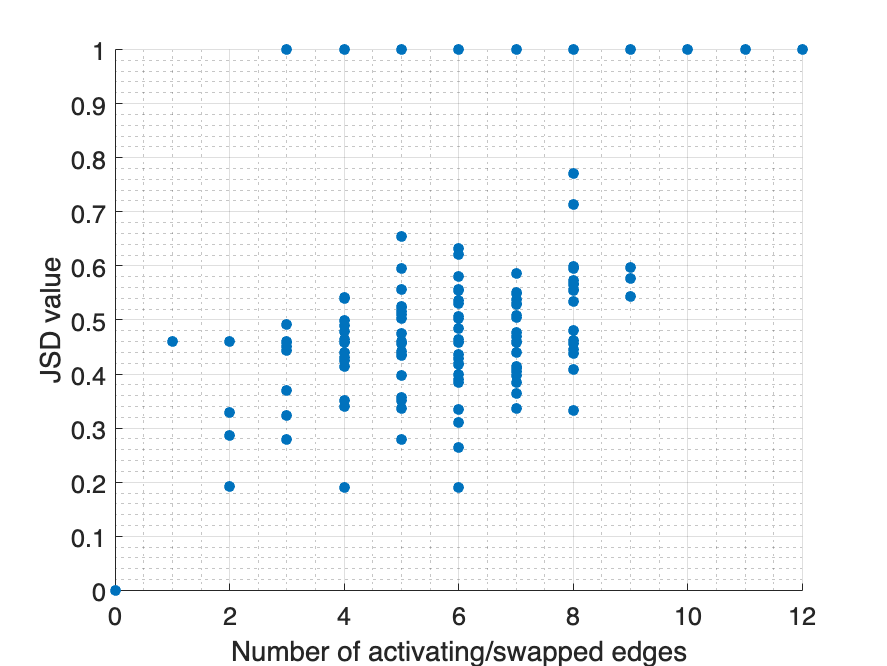

% pattern to extract only the number of activating edges form the file name
pat = '_' + digitsPattern;
network_order = str2double(extractBefore(file_names,pat));

figure()
scatter(network_order,jsd_values,'filled')
grid on; grid(gca,'minor');
% title('State Frequency JSD vs SA SI');
xlabel('Number of activating/swapped edges');
ylabel('JSD value');
% pbaspect([3 3 1]);
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',14)